# Remove Spikes from Sinusoid

Generate 100 samples of a sinusoidal signal. Replace the sixth and twentieth samples with spikes.

x = sin(2*pi*(0:99)/100);
x(6) = 2;
x(20) = -2;

Use `hampel` to locate every sample that differs by more than three standard deviations from the local median. The measurement window is composed of the sample and its six surrounding samples, three per side.

[y,i,xmedian,xsigma] = hampel(x);

Plot the filtered signal and annotate the outliers.

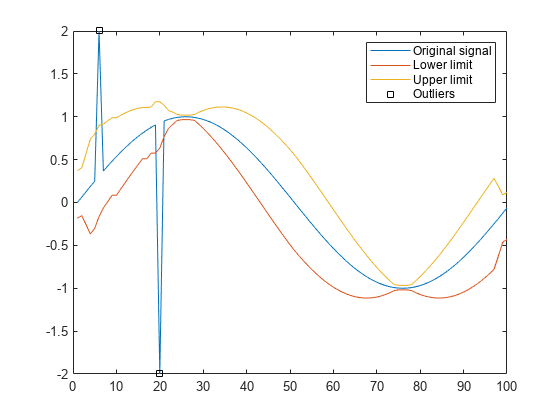

n = 1:length(x);
plot(n,x)
hold on
plot(n,xmedian-3*xsigma,n,xmedian+3*xsigma)
plot(find(i),x(i),'sk')
hold off
legend('Original signal','Lower limit','Upper limit','Outliers')

Repeat the computation, but now take just one adjacent sample on each side when computing the median. The function considers the extrema as outliers.

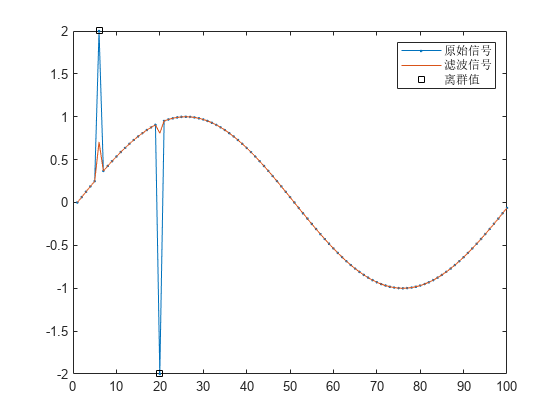

hampel(x,20)

*Copyright 2015 The MathWorks, Inc.*